** Introduction**

We created a fitness tracker especially made for hikers, by processing data collected from the **MATLAB Mobile** application in which we performed various physical activities (e.g., walking, running, sitting), while the application recorded data from built-in smartphone sensors such as GPS, accelerometer, and altimeter. The end goal is to extract meaningful metrics like total distance, number of steps, calories burned, and classify the type of physical activity. So that eventually the user can track the distance hike, the time spend hiking and a later display of his course. 

**TRAINING AND CLASSIFING OUR DATA **

% clc
% clear
close all;
% TRAINING
load('ExampleData.mat');
load ActivityLogs
head(sitAcceleration)

           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    20-Jul-2023 13:34:44.644      2.138    3.1268    10.077
    20-Jul-2023 13:34:44.724     1.1684    2.8754    8.8657
    20-Jul-2023 13:34:44.804    0.93134     3.146     9.335
    20-Jul-2023 13:34:44.884    0.69192    3.2729     8.746
    20-Jul-2023 13:34:44.964     1.1851    3.3974    9.1722
    20-Jul-2023 13:34:45.044     1.1803    3.4093    9.1626
    20-Jul-2023 13:34:45.124     1.0654    3.3423    8.6335
    20-Jul-2023 13:34:45.204     1.5778    3.5147    9.7779



sitLabel='sitting';
sitLabel=repmat(sitLabel,size(sitAcceleration,1),1);
sitAccelaration.Activity=sitLabel;
head(walkAcceleration)

           Timestamp               X           Y           Z    
    ________________________    ________    _______    _________

    21-Jul-2023 15:35:12.221     -3.1316    -13.139      -1.2474
    21-Jul-2023 15:35:12.301    -0.18196    -9.1937    -0.040701
    21-Jul-2023 15:35:12.381      -3.778    -9.7324       1.4916
    21-Jul-2023 15:35:12.461     -2.4828    -8.9447     -0.40941
    21-Jul-2023 15:35:12.541     -2.0423     -9.347      0.38068
    21-Jul-2023 15:35:12.621     -1.9178    -9.9024       1.2306
    21-Jul-2023 15:35:12.701     -5.0182    -12.292     -0.12929
    21-Jul-2023 15:35:12.781      -0.249    -9.6582       1.8818



walkLabel='walking';
walkLabel=repmat(walkLabel,size(walkAcceleration,1),1);
walkAccelaration.Activity=walkLabel;
head(runAcceleration)

           Timestamp               X           Y          Z    
    ________________________    ________    _______    ________

    21-Jul-2023 15:36:33.049    -0.88107     -7.446      4.6543
    21-Jul-2023 15:36:33.129     -6.5984    -12.555      6.2321
    21-Jul-2023 15:36:33.209     -4.2952     -6.426      6.2513
    21-Jul-2023 15:36:33.289    -0.60813    -1.8459     -2.6504
    21-Jul-2023 15:36:33.369      5.5474    -17.511     0.22984
    21-Jul-2023 15:36:33.449      -2.411    -7.7644      3.5147
    21-Jul-2023 15:36:33.529     -10.829    -14.614      9.9048
    21-Jul-2023 15:36:33.609     -0.3304     -4.707    -0.77333



runLabel='running';
runLabel=repmat(runLabel,size(runAcceleration,1),1);
runAccelaration.Activity=runLabel;
allAcceleration = [sitAcceleration; walkAcceleration;runAcceleration];
allAcceleration = timetable2table(allAcceleration,"ConvertRowTimes", false);
allAcceleration.Categories=[sitLabel;walkLabel;runLabel];
justAcc = timetable2table(unknownAcceleration, "ConvertRowTimes",false);
load('TRAINEDMODEL.mat');
yfit = TRAINEDMODEL.predictFcn(justAcc);

**Preparing Data**

To work with the data, we first load it into the workspace and store the variables of the example data so that we train a model classifier. 

load('ExampleData.mat');
lat=Position.latitude;
lon=Position.longitude;
alt=Position.altitude;
speedKmh=Position.speed;
positionDatetime=Position.Timestamp;
TimeStamp=Position.Timestamp;
Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

The user can input personal details such as weight, height, gender and hiking habits, the last although not used can provide more personalized tracking, analysis and a more user friendly approach.  

w = input('Weight(kg) :  ');
h = input('Heigt(cm) : ');
g = input('Gender : ');
hiker = input('How often do you hike ?(first time /occasionally /regularly/frequently)')

hiker = "first time"

**CALCULATION**

Calculation of distance , steps , time spent , calories and all the essential charachteristics mentioned above .

startTime = Acceleration.Timestamp(1);
endTime = Acceleration.Timestamp(end);
% Calculate the total duration in seconds
durationSec = seconds(endTime - startTime);

elevationGain = computeElevationGain(alt);
met = estimateMET(speedKmh, alt, durationSec);


% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(TimeStamp);
accelTime=timeElapsed(accelDatetime);
earthCirc = 24901;
totaldis = 0;

for i = 1:(length(lat)-1)
lat1 = lat(i); % The first latitude
lat2 = lat(i+1); % The second latitude
lon1 = lon(i); % The first longitude
lon2 = lon(i+1); % The second longitude
degDis = distance(lat1, lon1, lat2, lon2);
dis = (degDis/360)*earthCirc;
totaldis = totaldis + dis;
end

stride = 2.5; % Average stride (ft)
totaldis_ft = totaldis*5280; % Converting distance from miles to feet
steps = totaldis_ft/stride;

caloriesBurned=round(met*weight*durationSec/(60*60));

And the functions used .

function elevationRate = computeElevationRate(altitude, timeSec)
% timeSec: total duration in seconds
gain = computeElevationGain(altitude);
durationMin = timeSec / 60;
elevationRate = gain / durationMin; % meters per minute
end

function elevationGain = computeElevationGain(altitude)
% altitude: vector of altitude readings in meters
delta = diff(altitude);
elevationGain = sum(delta(delta > 0)); % only count positive changes
end

function met = estimateMET(speedKmh, elevationGainM, durationMin)
% Convert to rate of elevation gain per minute
elevationRate = elevationGainM / durationMin;
% Adjust MET based on speed and climbing rate
if speedKmh < 3
baseMet = 3.5;
elseif speedKmh < 5
baseMet = 5.0;
else
baseMet = 6.0;
end
% Increase MET for steeper climbs
if elevationRate > 5
met = baseMet + 1.0;
elseif elevationRate > 10
met = baseMet + 2.0;
else
met = baseMet;
end
end

**DISPLAY**

Eventually there is a display of the Hiking path, Elevation profile and Speed over time.

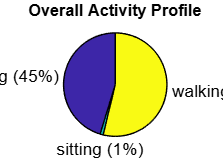

figure;
yfitcat = categorical(cellstr(yfit));
pie(yfitcat)
title("Overall Activity Profile");

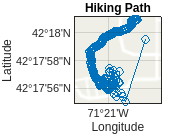



figure;
geoplot(lat, lon, '-o');
geobasemap topographic
title('Hiking Path');

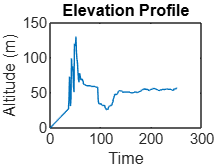


% Plot elevation vs time
figure;
plot(positionTime, alt, '-');
xlabel('Time');
ylabel('Altitude (m)');
title('Elevation Profile');

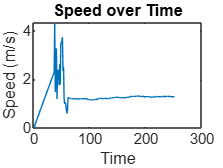


% Plot speed vs time
figure;
plot(positionTime, speedKmh, '-');
xlabel('Time');
ylabel('Speed (m/s)');
title('Speed over Time');